clearvars; close all; 
imtool close all;
% Store the size of the image this model takes in as imSize
%imSize = net.Layers(1).InputSize;

trainingFolderPath = "./TrainingData4"; %uigetdir(".", "Choose the downloaded trainingImages folder");
imds = imageDatastore(trainingFolderPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% To view the images in MATLAB - run the following commented line.
%imageBrowser(imds)

[img, imgInfo] = readimage(imds, 1)

img = 200×300×3 uint8 array
img(:,:,1) =

    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    72    

imgInfo = struct with fields:
    Filename: '/Users/franzgorlich/Documents/MATLAB/SwissAIHackathon/TrainingData4/Paper/t104l5I8TqdzF9WDMJ.png'
    FileSize: 34857
       Label: Paper



inputSize = size(img)

inputSize =    200   300     3


numClasses = 3

numClasses = 3


layers = [
    imageInputLayer(inputSize,'Name','input')

    convolution2dLayer(5,16,'Padding','same','Name','conv_1')
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1') 

    convolution2dLayer(3,32,'Padding','same','Stride',2,'Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')

    additionLayer(2,'Name','add')

    averagePooling2dLayer(2,'Stride',2,'Name','avpool')
    fullyConnectedLayer(numClasses,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classOutput')];

lgraph = layerGraph(layers)

lgraph =   LayerGraph with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
    Connections: [14×2 table]
     InputNames: {'input'}
    OutputNames: {'classOutput'}


skip_conv_layer = convolution2dLayer(1,32,'Stride',2,'Name','skipConv');
lgraph = addLayers(lgraph,skip_conv_layer);
lgraph = connectLayers(lgraph,'relu_1','skipConv');
lgraph = connectLayers(lgraph,'skipConv','add/in2');

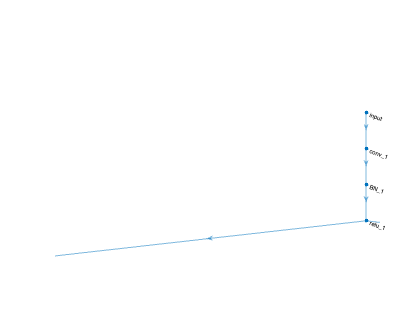

plot(lgraph);
axis off

[trainDS, testDS, validDS] = splitEachLabel(imds, 0.799, 0.001, 0.2);

% Here's one way to resize all images in a datastore - by using
% augmentedImageDatastore. 
imSize = inputSize

imSize =    200   300     3


validDS = augmentedImageDatastore(imSize(1:2), validDS);

% Another method: use transform function (recommended API) to resize all images in
% the test datastore.
testDS = transform(testDS, @(x) imresize(x, imSize(1:2)));

% For the training set - use imageDataAugmenter - you could also do this
% with transform - try that out if you'd like!
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-50 50], ...
                               'RandRotation', [-180 180]);

trainingData = augmentedImageDatastore(imSize(1:2),trainDS,'DataAugmentation',augmenter);

% numCats holds the number of categories of labels - 3 in our case.
numCats = numel(categories(imds.Labels));

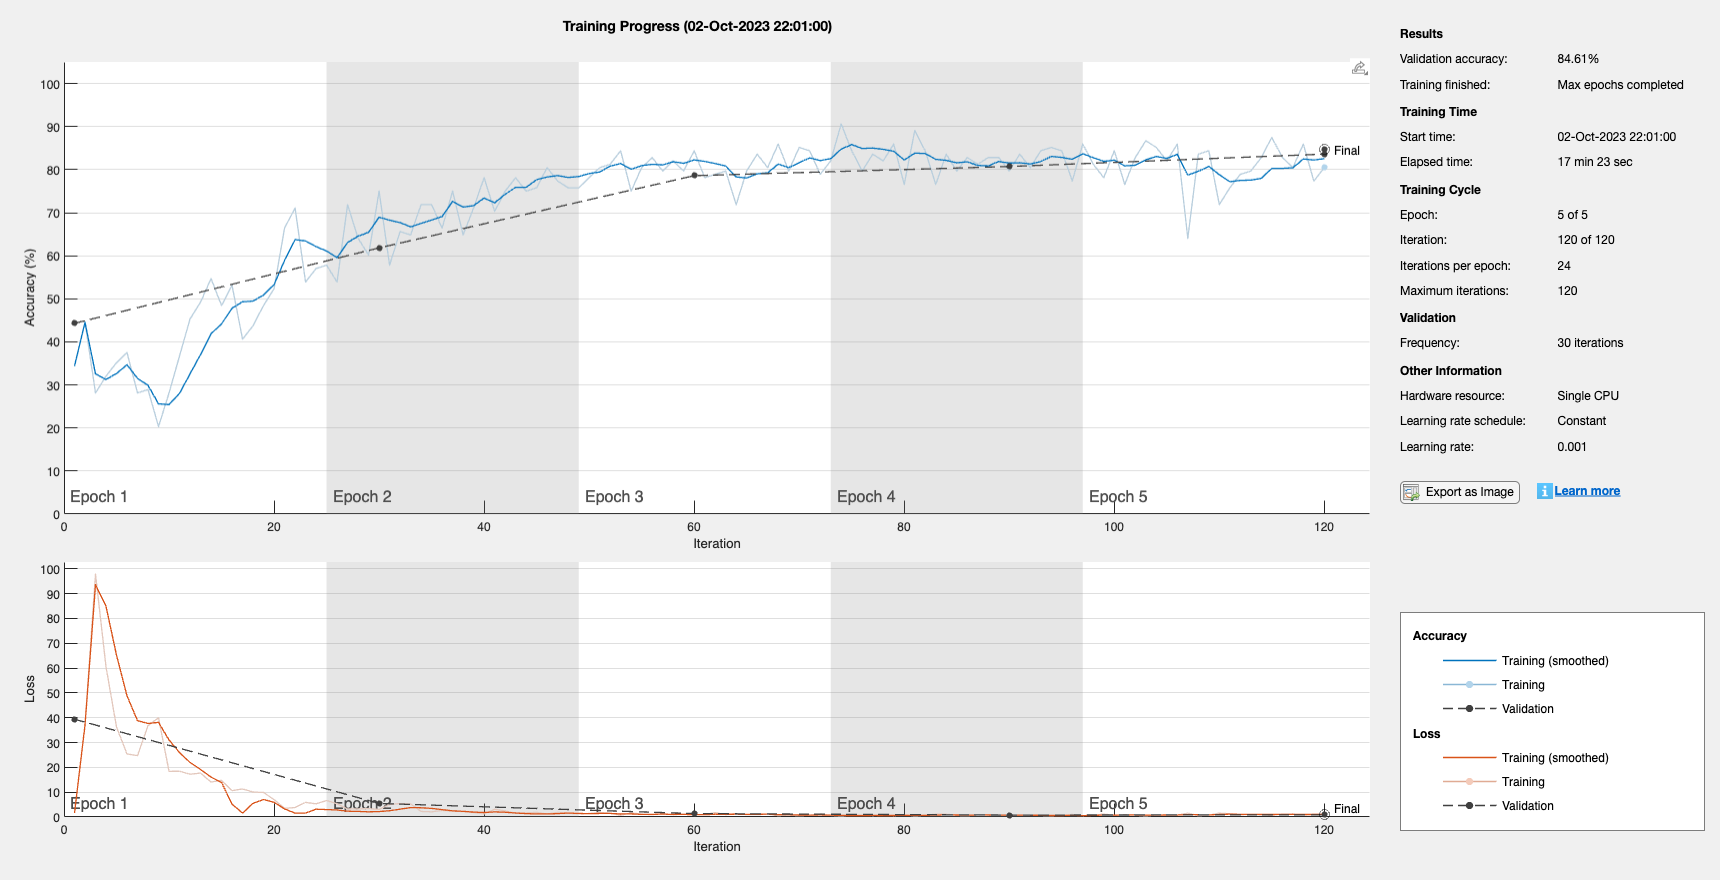

options = trainingOptions('adam', ...
'InitialLearnRate',0.001, ...
'MaxEpochs',5, ...
'Shuffle','every-epoch', ...
'ValidationData',validDS, ...
'ValidationFrequency',30, ...
'Verbose',false, ...
'Plots','training-progress' ...
);

net = trainNetwork(trainDS,lgraph,options);

net.Connections

ans = 16×2 table
       Source         Destination  
    ____________    _______________

    {'input'   }    {'conv_1'     }
    {'conv_1'  }    {'BN_1'       }
    {'BN_1'    }    {'relu_1'     }
    {'relu_1'  }    {'conv_2'     }
    {'relu_1'  }    {'skipConv'   }
    {'conv_2'  }    {'BN_2'       }
    {'BN_2'    }    {'relu_2'     }
    {'relu_2'  }    {'conv_3'     }
    {'conv_3'  }    {'BN_3'       }
    {'BN_3'    }    {'relu_3'     }
    {'relu_3'  }    {'add/in1'    }
    {'add'     }    {'avpool'     }
    {'avpool'  }    {'fc'         }
    {'fc'      }    {'softmax'    }
    {'softmax' }    {'classOutput'}
    {'skipConv'}    {'add/in2'    }


save('skipNet1D4.mat','net');


[YTest, scores] = classify(net, testDS);

% Also measure accuracy - this is the percentage of matching labels in the
% test set. Note that we use the 'UnderlyingDatastore' part of the test
% dataset (because it is a 'transform' datastore to retrieve the labels.
TTest = testDS.UnderlyingDatastore.Labels;
accuracy = sum(YTest == TTest)/numel(YTest)

accuracy = 1

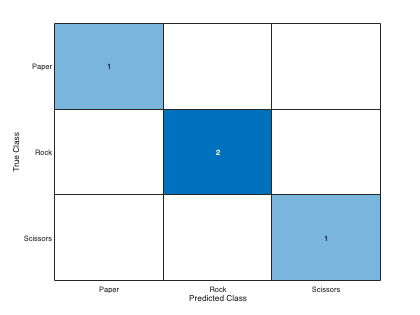

% Also plot the confusion chart.
confusionchart(TTest, YTest)

load(latest_model_name,"convnet");

Unrecognized function or variable 'latest_model_name'.

mynet = convnet;
% Choose a random index from 1 to 200.
idx = randi(200, 1);
img = readimage(testDS.UnderlyingDatastore, idx);
img = imresize(img, [224 224]);

imR = imresize(img, mynet.Layers(1).InputSize(1:2));
label = classify(mynet, imR)

figure,
imshow(img)
title(fprintf("Predicted label: %s", label))

## Submitting your trained model to the leaderboard

Finally, if you are sufficiently satisfied with the performance of your trained model in the "final exam" of generalization, it is time to submit it to our secret test set (with more complicated images in different backgrounds and lighting conditions), to find out where you stand on the leaderboard! The below function will test your model against an online test set, and sends it to our leaderboard application. This process might take some minutes, and once done, your model will also be uploaded to an online repository, which might be used for the final evaluation of the competition.

Please supply your model and team name to the `submit` function as first and second argument, respectively. Please note that the model should be of the datatype "DAGNetwork".

team_name = "lever tf up";
submit(net, team_name)

Godspeed, and we wish you the best of luck in topping the charts! You have a whole week to stay up there, so remember the pole position can be overtaken by someone else! 

### Open the Leaderboard and compare with Competitors

You can open the leaderboard with the below command. Once the window opens you can synchronize it by clicking on the start button.

LeaderBoard

*Copyright 2023, The MathWorks, Inc.*